## Constant variables

clear all;
Ea = 13.4E10; %elastic modulus ceramic
Em = 210E9; %elastic modulus steel

## Linear system

S = 20;
S0 = 3.3;
h0 = 2;
hl = (S/S0 + 1) * h0 *1E-3;
wl = 15E-3; %sqrt(1000/42);  

Cal = Ea * wl^2 / hl

Cal = 2.1351e+09

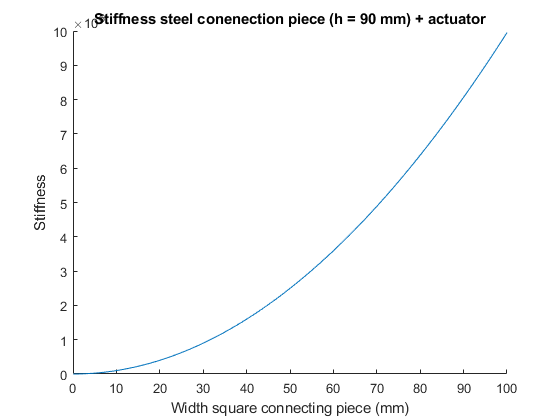


width = transpose([0.1:0.1:100]*1E-3);

L = length(width);
Ccl = zeros(L,1);
Cacl = zeros(L,1);
for i=1:L
    Ccl(i) = Em * (width(i))^2 / 90;
    Cacl(i) = (1/Cal + 1/Ccl(i))^-1;
end


figure
clf;
hold on
plot(width*1E3,Cacl)
ylabel('Stiffness')
xlabel('Width square connecting piece (mm)')
title('Stiffness steel conenection piece (h = 90 mm) + actuator')

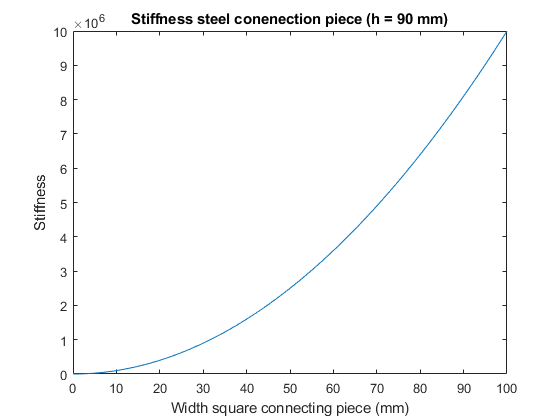


figure()
clf
plot(width*1E3,Ccl)
ylabel('Stiffness')
xlabel('Width square connecting piece (mm)')
title('Stiffness steel conenection piece (h = 90 mm)')

%ylim([0,0.5E13])

## Simple lever system

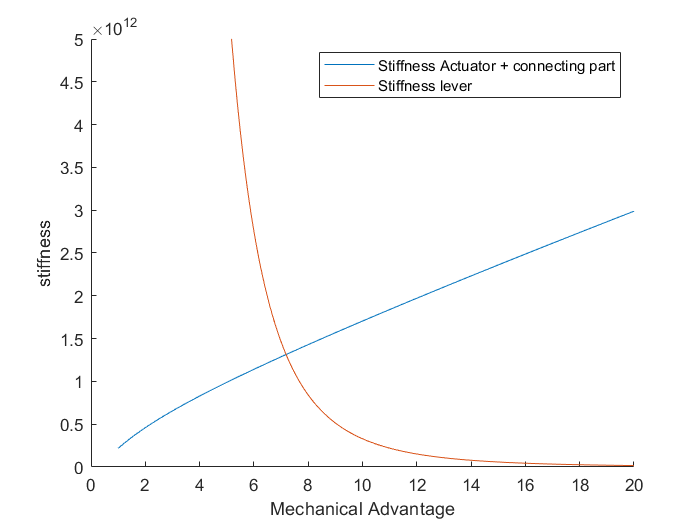

Ma = transpose([1:0.1:20]);
L = length(Ma);
h = zeros(L,1);
w = zeros(L,1);
Ca = zeros(L,1);
Cc = zeros(L,1);
Cac = zeros(L,1);
Cl = zeros(L,1);
Fb = zeros(L,1);
lever = zeros(L,1);
leverHeight = zeros(L,1);

totalLength = 90;
leverWidth = 40; 
for i = 1: L 
    MA = Ma(i); %mechanical advantage of the system
    S = 10;
    S0 = 3.3;
    h0 = 2;
    h(i) = (1/MA) * (S/S0 + 1) * h0;
    
    Fb(i) = 1000 * MA; %N force on the actuator after mechanical advantage is applied
    w(i) = sqrt(Fb(i)/42);   

    
    Ca(i) = Ea * w(i)^2 / h(i);
    Cc(i) = Em * (w(i) + 5)^2 / (50 - h(i));
    Cac(i) = (1/Ca(i) + 1/Cc(i))^-1;
    lever(i) = w(i) * (MA + 1);
    leverHeight(i) = 40;

    I = leverHeight(i)^3 * leverWidth;
    Cl(i) = 3 * Em * I / lever(i)^3; %bending stiffness
end

figure 
clf;
hold on
plot(Ma,Cac)
plot(Ma,Cl)
legend("Stiffness Actuator + connecting part","Stiffness lever")
ylim([0,0.5E13])
ylabel('stiffness')
xlabel('Mechanical Advantage')

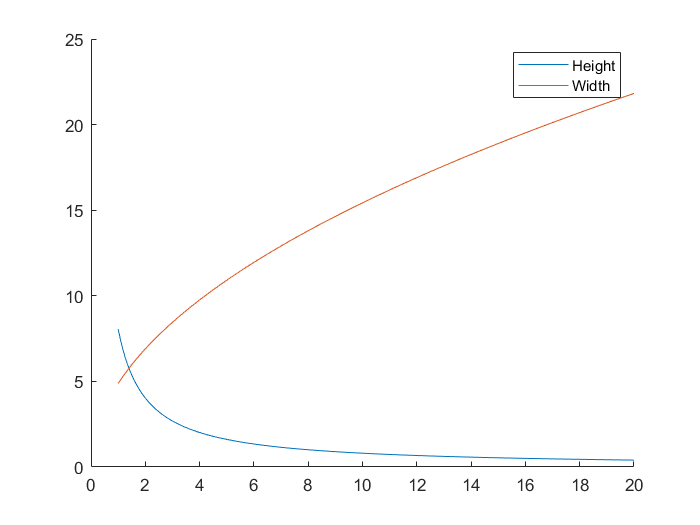

figure()
clf;
hold on
plot(Ma,h)
plot(Ma,w)
legend("Height","Width")


table(Ma,Ca,Cl,h,w,lever,leverHeight,Fb)

ans = 91×8 table
    Ma         Ca            Cl          h         w       lever     leverHeight     Fb 
    ___    __________    __________    ______    ______    ______    ___________    ____

      1    2.2594e+11    1.7353e+15    14.121    4.8795     9.759        40         1000
    1.1    2.7338e+11    1.2993e+15    12.837    5.1177    10.747        40         1100
    1.2    3.2535e+11    9.9178e+14    11.768    5.3452    11.759        40         1200
    1.3    3.8183e+11    7.6976e+14    10.862    5.5635    12.796        40         1300
    1.4    4.4283e+11    6.0622e+14    10.087    5.7735    13.856        40         1400
    1.5    5.0835e+11    4.8361e+14    9.4141    5.9761     14.94        40         150

### Simple lever system with more variables

Ma0 = 1;  Ma1 = 50;
lH0 = 0;  lH1 = 80;
stepsize = 1;
[X,Y] = meshgrid(Ma0:stepsize:Ma1,lH0:stepsize:lH1);
Ma = transpose([Ma0:stepsize:Ma1]);
leverHeight = ([lH0:stepsize:lH1]);
L1 = length(leverHeight);
L2 = length(Ma);
h = zeros(L1,L2);
w = zeros(L1,L2);
Ca = zeros(L1,L2);
Cc = zeros(L1,L2);
Cac = zeros(L1,L2);
Cl = zeros(L1,L2);
Fb = zeros(L1,L2);
lever = zeros(L1,L2);

totalHeight = 90;
leverWidth = 40;
for i = 1 : L1
    for j = 1 : L2 
        MA = Ma(j); %mechanical advantage of the system
        S = 10;
        S0 = 3.3;
        h0 = 2;
        h(i,j) = (1/MA) * (S/S0 + 1) * h0;
        
        Fb(i,j) = 1000 * MA; %N force on the actuator after mechanical advantage is applied
        w(i,j) = sqrt(Fb(i)/42);   
    
        actuatorHeight = totalHeight - leverHeight(i);
        Ca(i,j) = Ea * w(i,j)^2 / h(i,j);
        Cc(i,j) = Em * (w(i,j) + 5)^2 / (actuatorHeight - h(i,j));
        Cac(i,j) = (1/Ca(i,j) + 1/Cc(i,j))^-1;
        lever(i,j) = w(i,j) * (MA + 1);
    
    
        I = leverHeight(i)^3 * leverWidth;
        Cl(i,j) = 3 * Em * I / lever(i,j)^3; %bending stiffness
    end
end

dim = size(Cl)

dim =     81    50


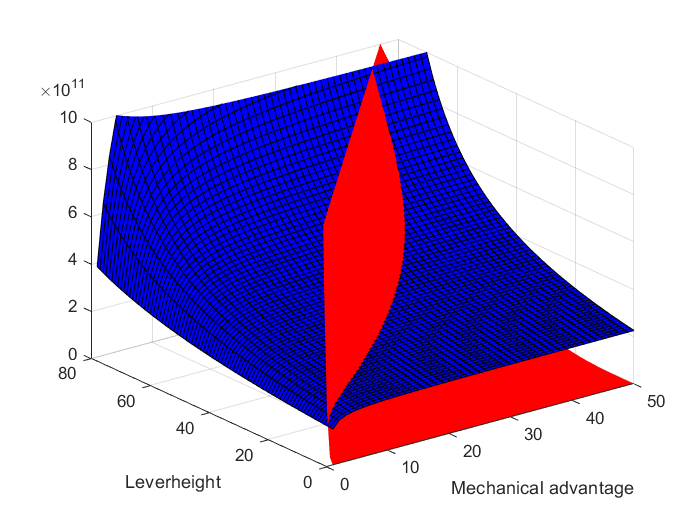


figure 
clf
hold off

colormap([1 0 0;0 0 1])
s1 = surf(X,Y,Cl,ones(dim));
s1.EdgeColor = 'none';
zlim([0 10]*1E11)
hold on
s2 = surf(X,Y,Cac,ones(dim)+1);
%s2.EdgeColor = 'none';
xlabel("Mechanical advantage")
ylabel("Leverheight")

%legend('stiffness lever','stiffness actuator')
